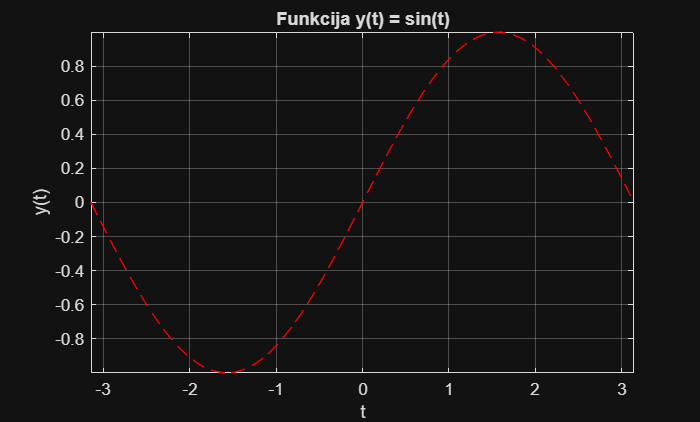

% Ieva Umaraitė EIRf-25 2026-09-28
% Rezultatų grafinis 2D atvaizdavimas

clear
close all

% a) Dvimatis grafikų vaizdavimas

t = linspace(-pi, pi, 50);
y = sin(t);

figure(1);
plot(t, y, 'r--');
title('Funkcija y(t) = sin(t)');
xlabel('t');
ylabel('y(t)');
axis([min(t) max(t) min(y) max(y)]); 
grid on;

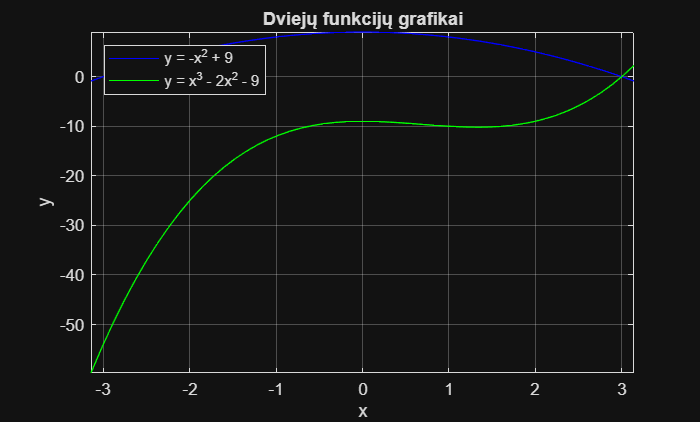


% b) y1(x) ir y2(x)
x = linspace(-pi, pi, 50);
y1 = -x.^2 + 9;
y2 = x.^3 - 2*x.^2 - 9;

figure(2);
plot(x, y1, 'b-', x, y2, 'g-');
title('Dviejų funkcijų grafikai');
xlabel('x');
ylabel('y');
legend('y = -x^2 + 9', 'y = x^3 - 2x^2 - 9', 'Location', 'northwest');

% Ašių ribų nustatymas 
xmin = min(x);
xmax = max(x);
ymin = min([y1 y2]);
ymax = max([y1 y2]);
axis([xmin xmax ymin ymax]);
grid on;

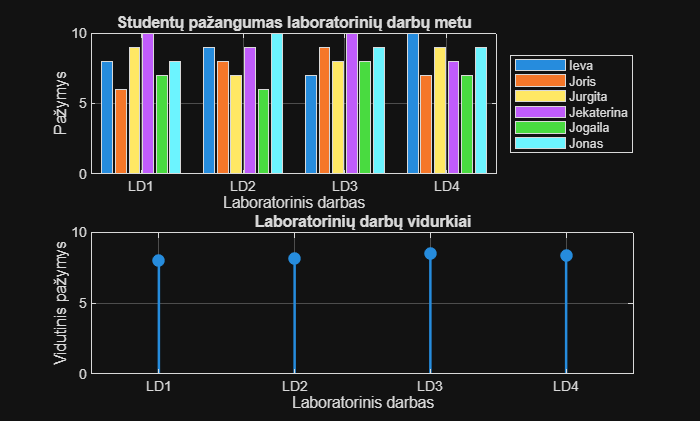



% Specializuotų grafikų kūrimas

vardai = {'Ieva', 'Joris', 'Jurgita', 'Jekaterina', 'Jogaila', 'Jonas'};
pazymiai = [
    8  9  7  10;
    6  8  9   7;
    9  7  8   9;
    10 9  10  8;
    7  6  8   7;
    8  10 9   9
];

laboratoriniai = 1:4;
vidurkiai = mean(pazymiai, 1);

figure(3);


subplot(2, 1, 1);
bar(pazymiai'); 

title('Studentų pažangumas laboratorinių darbų metu');
xlabel('Laboratorinis darbas');
ylabel('Pažymys');
set(gca, 'XTick', 1:4);
set(gca, 'XTickLabel', {'LD1', 'LD2', 'LD3', 'LD4'});
ylim([0 10]);
grid on;
legend(vardai, 'Location', 'eastoutside'); 

% 2 grafikas 
subplot(2, 1, 2);
stem(laboratoriniai, vidurkiai, 'filled', 'LineWidth', 1.5);

title('Laboratorinių darbų vidurkiai');
xlabel('Laboratorinis darbas');
ylabel('Vidutinis pažymys');
xlim([0.5 4.5]);
ylim([0 10]);
set(gca, 'XTick', 1:4);
set(gca, 'XTickLabel', {'LD1', 'LD2', 'LD3', 'LD4'});
grid on;

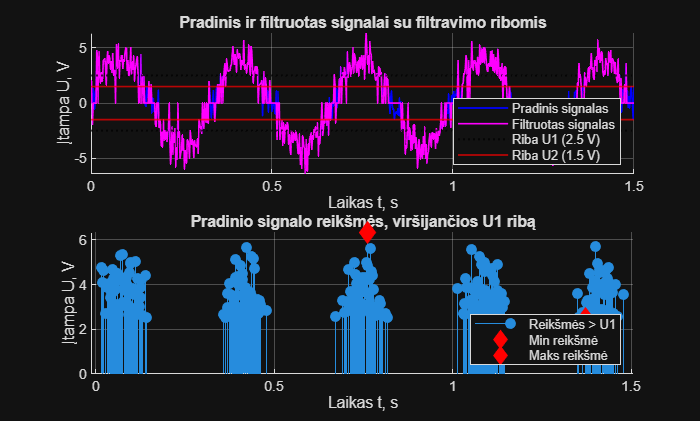




% Signalų grafinis atvaizdavimas


A = 4;             
f = 3;            
sigma = 1;         
U1 = 2.5;         
U2 = 1.5;

t_sig = 0:0.002:1.5;

s_cist = A * sin(2 * pi * f * t_sig);  
rng(0); 
n = sigma * randn(size(t_sig));        
s = s_cist + n;                  


s_filtruotas = s;
s_filtruotas(abs(s_filtruotas) < U2) = 0;

ind_atrinkti = s > U1;
t_atrinktas = t_sig(ind_atrinkti);
s_atrinktas = s(ind_atrinkti);

figure(4);

% a) Pirmas grafikas 
subplot(2, 1, 1);
hold on;

plot(t_sig, s, 'b', 'LineWidth', 1, 'DisplayName', 'Pradinis signalas');
plot(t_sig, s_filtruotas, 'm', 'LineWidth', 1, 'DisplayName', 'Filtruotas signalas');

yline(U1, ':k', 'LineWidth', 1.25, 'DisplayName', 'Riba U1 (2.5 V)');
yline(-U1, ':k', 'LineWidth', 1.25, 'HandleVisibility', 'off');

yline(U2, '-r', 'LineWidth', 1, 'DisplayName', 'Riba U2 (1.5 V)');
yline(-U2, '-r', 'LineWidth', 1, 'HandleVisibility', 'off');

hold off;
grid on;
title('Pradinis ir filtruotas signalai su filtravimo ribomis');
xlabel('Laikas t, s');
ylabel('Įtampa U, V');
legend('Location', 'southeast');

% b) Antras
subplot(2, 1, 2);
hold on;

stem(t_atrinktas, s_atrinktas, 'filled', 'DisplayName', 'Reikšmės > U1');

% visos min ir max reikšmės
min_val = min(s_atrinktas);
max_val = max(s_atrinktas);

idx_min = find(s_atrinktas == min_val);
idx_max = find(s_atrinktas == max_val);

plot(t_atrinktas(idx_min), min_val, 'rd', 'MarkerSize', 9, 'MarkerFaceColor', 'r', 'DisplayName', 'Min reikšmė');
plot(t_atrinktas(idx_max), max_val, 'rd', 'MarkerSize', 9, 'MarkerFaceColor', 'r', 'DisplayName', 'Maks reikšmė');

hold off;
grid on;
title('Pradinio signalo reikšmės, viršijančios U1 ribą');
xlabel('Laikas t, s');
ylabel('Įtampa U, V');
legend('Location', 'southeast');